# Bridge of Doom

Sam Coleman and Rishita Sarin

parametric equation: r(u) = 4*(.396cos(2.65(u+1.4))i - .99sin(u+1.4)j), u in set [0, 3.2]

clc, clear all

syms beta t

ri = 4*0.396*cos(2.65*(beta * t + 1.4));
rj = 4*-0.99*sin(beta * t+ 1.4);
rk = 4*0*t;
r=[ri,rj,rk];

dr=diff(r,t);

assume(beta,{'real','positive'})
assume(t,{'real','positive'})

T_hat=simplify(dr./norm(dr))

dT_hat=diff(T_hat,t);

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,\beta \,t}{20}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(\beta \,t+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2809\,{\sin\left(\frac{53\,\beta \,t}{20}+\frac{371}{100}\right)}^{2}+2500\,{\cos\left(\beta \,t+\frac{7}{5}\right)}^{2}} \end{array}$$

N_hat=simplify(dT_hat/norm(dT_hat))

B_hat=simplify(cross(T_hat,N_hat))

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{50\,\sigma_{3}}{\sigma_{1}} & \frac{53\,\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\sigma_{3}}^{2}+2809\,{\sigma_{2}}^{2}}\\ \sigma_{2}=40\,\sin\left(\beta \,t+\frac{7}{5}\right)+73\,\sin\left(\frac{43\,\beta \,t}{10}+\frac{301}{50}\right)+33\,\sin\left(\frac{63\,\beta \,t}{10}+\frac{441}{50}\right)\\ \sigma_{3}=73\,\cos\left(\frac{13\,\beta \,t}{20}+\frac{91}{100}\right)+106\,\cos\left(\frac{53\,\beta \,t}{20}+\frac{371}{100}\right)+33\,\cos\left(\frac{93\,\beta \,t}{20}+\frac{651}{100}\right) \end{array}$$


kappa=simplify(norm(dT_hat)/norm(dr));

$$B\_hat = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & -\frac{91250\,\cos\left(\frac{7\,\beta \,t}{20}+\frac{49}{100}\right)+\frac{764917\,\cos\left(\frac{33\,\beta \,t}{20}+\frac{231}{100}\right)}{2}+\frac{327837\,\cos\left(\frac{73\,\beta \,t}{20}+\frac{511}{100}\right)}{2}+41250\,\cos\left(\frac{113\,\beta \,t}{20}+\frac{791}{100}\right)-\frac{205057\,\cos\left(\frac{139\,\beta \,t}{20}+\frac{973}{100}\right)}{2}-\frac{92697\,\cos\left(\frac{179\,\beta \,t}{20}+\frac{1253}{100}\right)}{2}}{\sqrt{2500\,{\left(73\,\cos\left(\frac{13\,\beta \,t}{20}+\frac{91}{100}\right)+106\,\cos\left(\sigma_{1}\right)+33\,\cos\left(\frac{93\,\beta \,t}{20}+\frac{651}{100}\right)\right)}^{2}+2809\,{\left(40\,\sin\left(\sigma_{2}\right)+73\,\sin\left(\frac{43\,\beta \,t}{10}+\frac{301}{50}\right)+33\,\sin\left(\frac{63\,\beta \,t}{10}+\frac{441}{50}\right)\right)}^{2}}\,\sqrt{2809\,{\sin\left(\sigma_{1}\right)}^{2}+2500\,{\cos\left(\sigma_{2}\right)}^{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{53\,\beta \,t}{20}+\frac{371}{100}\\ \sigma_{2}=\beta \,t+\frac{7}{5} \end{array}$$


tau=-N_hat*(diff(B_hat,t)/norm(dr))';

%these two lines are to make VL and VR always below 2m/s
%since u = beta*t, u still within the range [0, 3.2]
t_num = linspace(0,10,100); 
beta_num = .32;

for n=1:length(t_num)
    r_num(n,:)=double(subs(r, [beta, t], [beta_num, t_num(n)]));
    T_hat_num(n,:)=double(subs(T_hat,[beta, t], [beta_num, t_num(n)]));
    N_hat_num(n,:)=double(subs(N_hat, [beta, t], [beta_num, t_num(n)]));
    B_hat_num(n,:)=double(subs(B_hat, [beta, t], [beta_num, t_num(n)]));
    
end
figure(), clf
hold on
plot3(r_num(:,1),r_num(:,2),r_num(:,3), 'k'), axis equal
for n = 1:20:100
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),T_hat_num(n,1),T_hat_num(n,2),T_hat_num(n,3),'r') % plot the unit tangent
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),N_hat_num(n,1),N_hat_num(n,2),N_hat_num(n,3),'b') % plot the unit normal
end
title('Parametric Curve Center Line')
legend('Cener Line of Path', 'Unit Tangent Vector', 'Unit Normal Vector')
hold off

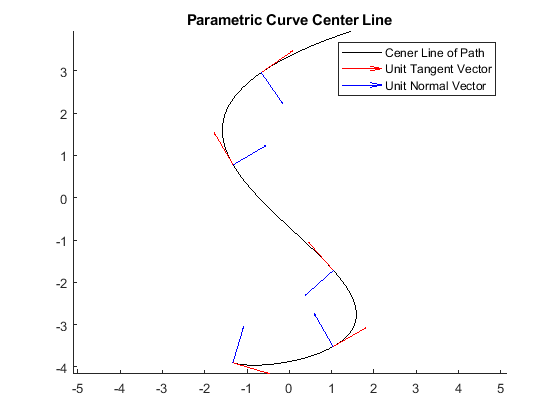

%36.2
syms omega d

omega = simplify(cross(T_hat, dT_hat));
v_R = simplify(norm(dr) + omega(3)*(d/2))
v_L = simplify(norm(dr) - omega(3)*(d/2))

d_num = .235;

$$v\_R = \frac{99\,\beta \,\sqrt{2809\,{\sin\left(\frac{53\,\beta \,t}{20}+\frac{371}{100}\right)}^{2}+2500\,{\cos\left(\beta \,t+\frac{7}{5}\right)}^{2}}}{1250}-\frac{265\,\beta \,d\,\left(73\,\cos\left(\frac{33\,\beta \,t}{20}+\frac{231}{100}\right)+33\,\cos\left(\frac{73\,\beta \,t}{20}+\frac{511}{100}\right)\right)}{2\,\left(5000\,\cos\left(2\,\beta \,t+\frac{14}{5}\right)-5618\,\cos\left(\frac{53\,\beta \,t}{10}+\frac{371}{50}\right)+10618\right)}$$

figure(), clf

$$v\_L = \frac{99\,\beta \,\sqrt{2809\,{\sin\left(\frac{53\,\beta \,t}{20}+\frac{371}{100}\right)}^{2}+2500\,{\cos\left(\beta \,t+\frac{7}{5}\right)}^{2}}}{1250}+\frac{265\,\beta \,d\,\left(73\,\cos\left(\frac{33\,\beta \,t}{20}+\frac{231}{100}\right)+33\,\cos\left(\frac{73\,\beta \,t}{20}+\frac{511}{100}\right)\right)}{2\,\left(5000\,\cos\left(2\,\beta \,t+\frac{14}{5}\right)-5618\,\cos\left(\frac{53\,\beta \,t}{10}+\frac{371}{50}\right)+10618\right)}$$

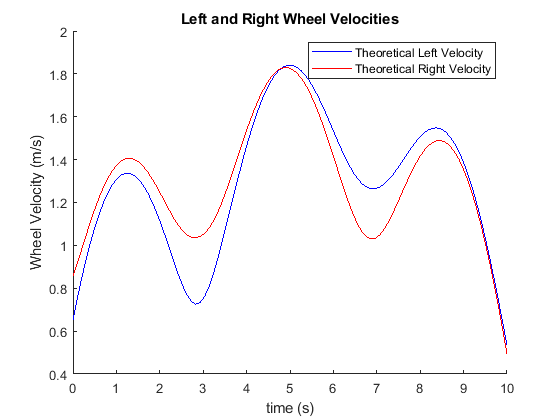

for n = 1:length(t_num)
    v_left(n) = double(subs(v_L, [beta, t, d], [beta_num, t_num(n), d_num]));
    v_right(n) = double(subs(v_R, [beta, t, d], [beta_num, t_num(n), d_num]));

end
hold on
plot(t_num,v_left, 'b')
plot(t_num,v_right, 'r')
title('Left and Right Wheel Velocities')
legend('Theoretical Left Velocity', 'Theoretical Right Velocity')
xlabel('time (s)')
ylabel('Wheel Velocity (m/s)')
hold off
